source_parameters = {'BARE','BARE'};

parameters= {'CA10','CB10'};

%DOE_range1 = [4.0, 10.0; 3, 8.0]; 
DOE_range1 = [0.15, 0.35; 0.100,  0.25];

%DOE experiment for 2 varaibles using Central Composite Design
Central_composite_points = ccdesign(2, 'type', 'inscribed', 'center' , 1);

DOE_sample_points10 = reverse_normalization(Central_composite_points, DOE_range1);
%DOE_sample_points2 = reverse_normalization(Central_composite_points, DOE_range2);
%DOE_sample_points3 = reverse_normalization(Central_composite_points, DOE_range3);

%DOE_sample_points = [DOE_sample_points ;reverse_normalization(Central_composite_points, DOE_range2)];
root_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_10';
simulation_seed_folder = fullfile(root_folder, 'Initial_files');
%simulation_seed_folder  = "C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_linear\Parameter_BARE_Zone1\Initial_files1";

collection_dir = fullfile(root_folder, 'Simulation_results');

parameters_np_array1 = convert_arr_to_python_2d_list(DOE_sample_points10);

snapshots_py = py.BEASY_IN_OUT2.snapshots_for_given_parameters_and_IDs(py.list(source_parameters), py.list(parameters), parameters_np_array1, py.list(IDs), py.list(response_data_type), simulation_seed_folder, collection_dir, py.list(IDs_types));

snapshots_10 = double(snapshots_py);

surrogates_10 = response_surface(DOE_sample_points10, snapshots_10, 2);
%}

%%{
root_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_10';

files_name = 'BU_TimeStepped_01_10';

calib_dir = fullfile(root_folder,'Calibration_data');
%calib_dir1 = 'C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_nonlinear\Parameter_BARE_BBS\caliburement_results3';


calib_data_file_err_inc = 'data_with_error.xlsx';

if ~isfile(fullfile(calib_dir, calib_data_file_err_inc))
    all_position_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(calib_dir, files_name, py.list(calib_data_type),  py.list(IDs), py.list(IDs_types));
    all_position_data = convert_pydict2data(all_position_dict,0);
    introduce_error_and_write_file( {IPs_IDs1.', IDs_current_density.'},all_position_data, calib_dir, calib_data_file_err_inc,1);
end
%model_out = output_from_surrogates([2.0, 3.0], surrogates, [17,6]);

calib_data_inc_error = data_from_tables(fullfile(calib_dir, calib_data_file_err_inc), calib_data_IDs,3);

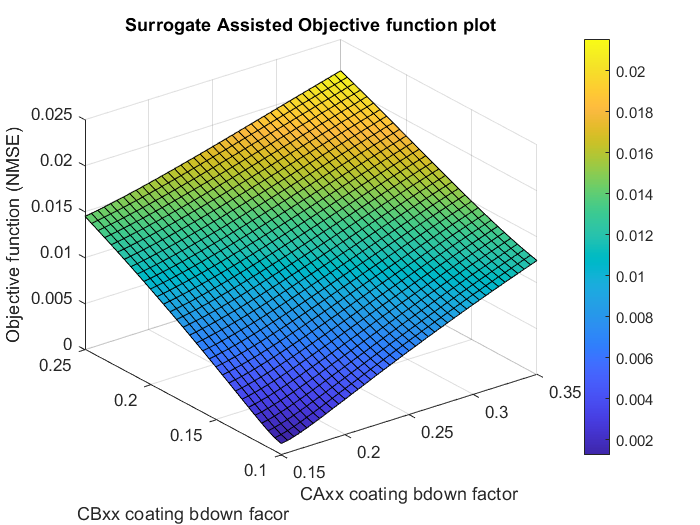

figure;

ax = gca;

[plot_data, fmin, min_out_pos1] = plot_objective_with_surrogates(ax, DOE_range1, surrogates_10, calib_data_inc_error, 'nmsq', calib_data_type, [length(IDs{1}), length(IDs{2})],[1,0], [0.005,0.005]);

sol_output_from_surrogate = output_from_surrogates(min_out_pos1, surrogates_10,[length(IDs{1}), length(IDs{2})]); 

xlabel('CAxx coating bdown factor');
ylabel('CBxx coating bdown facor');

min_out_pos1

min_out_pos1 =     0.1500    0.1000


%testing_par_value = min_out_pos1;
testing_par_value = [0.12 0.09];

sol_output_from_surrogate = output_from_surrogates(testing_par_value, surrogates_0,cellfun('length',IDs_matarr)); 


parameters= {'CA10','CB10'};

root_folder = 'C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_10';
simulation_seed_folder = fullfile(root_folder, 'Initial_files');
files_name = 'BU_TimeStepped_01_10';

solution_folder = '';
for i = 1:length(parameters)
    solution_folder =   strcat(solution_folder, parameters{i},'_', num2str(testing_par_value(i), '%.4f'));
    if i~=length(parameters)
        solution_folder = strcat(solution_folder, '_');
    end
end
solution_colection_dir = fullfile(root_folder,'Solution_results');

solution_dir = fullfile(solution_colection_dir, solution_folder);

if ~isfolder(solution_dir)
    solution_dict = py.BEASY_IN_OUT2.get_response_data_for_IDs_and_input_parameters(py.list(source_parameters), py.list(parameters), testing_par_value, simulation_seed_folder, solution_colection_dir,  py.list(response_data_type), py.list(IDs),  py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,1);
else

    solution_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(solution_dir, files_name, py.list(response_data_type),  py.list(IDs), py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,0);
end

figure;

ax = gca;

%difference_in_bar_chart(ax,solution_data{1}(1:3:end,:), calib_data_inc_error{1}(1:3:end,:),{'simulation data from calibrated model','calibration data', 'difference'});
%difference_in_bar_chart(ax,solution_data{1}(1:3:end,:), output_from_surrogate{1}(1:3:end,:),{'simulation data from calibrated model','calibration data', 'difference'});
%difference_in_bar_chart(ax,solution_data{3}(1:25:end,:), sol_output_from_surrogate{3}(1:25:end,:),{'simulation output data','surrogate output data', 'difference'});
%difference_in_bar_chart(ax,solution_data{1}(1:3:end,:), sol_output_from_surrogate{1}(1:3:end,:),{'simulation output data','surrogate output data', 'difference'});


difference_in_bar_chart(ax,solution_data{2}, sol_output_from_surrogate{2},{'simulation output data','surrogate output data', 'difference'});


%set(ax,'XAxisLocation','bottom');

xlabel('Mesh Points IDs');
%xlabel('anode IDs');
%ylabel('consumption rate (kg/yr)')
ylabel('normal directional current density');
%ylim([-1100 -950]);
%}

figure;
ax = gca;
legend_cell = {  'simulation output data','output from surrogate'};
%legend_cell = { 'output from calibrated surrogate', 'simulation output of calibrated model'};

data_ID = 1;
response_in_bar_chart(ax, solution_data{data_ID}(1:3:end,:) , {solution_data{data_ID}(1:3:end,:), sol_output_from_surrogate{data_ID}(1:3:end,:)}, legend_cell);
%response_in_bar_chart(ax, solution_data{data_ID} , {calib_data_15{data_ID}, sol_output_from_surrogate{data_ID}, solution_data{data_ID}}, legend_cell);
%response_in_bar_chart(ax, solution_data{data_ID} , { solution_data{data_ID},sol_output_from_surrogate{data_ID}},  legend_cell);


%ylabel('anode Current');
%ylim([1200 2000]);

%set(ax,'XAxisLocation','bottom');

%xlabel('Internal Points IDs');
%xlabel('Mesh Points IDs');
%xlabel('anode IDs');
%ylabel('anode consumption rate (kg/yr)')
%ylabel('Z electric field (micro-V/m)');
%ylabel('Normal current density');
%ylim([-1040 -990]);

%ylim([11 16]);

%}


function output_data = convert_pydict2data2(py_dict_data, extra_cell_provided)

output_data = cell(size(py_dict_data,2)-extra_cell_provided,1);

for i = 1:size(py_dict_data,2)-extra_cell_provided
    output_data{i} = convert_py_list_to_mat_arr(py.model_validation1.get_list_of_values(py_dict_data{i+extra_cell_provided}));
end
end


function de_normaised_data = reverse_normalization(normalised_data, value_ranges)

de_normaised_data = zeros(size(normalised_data));

for i = 1:size(normalised_data, 2)
    
    de_normaised_data(:,i) = value_ranges(i,1)+ diff(value_ranges(i,:))/2 * (normalised_data(:,i)-(-1));
    
end
end